Alen Mehmedbegovic - January 11th, 2024 

MATLAB matrix review

10:-1:1

ans =     10     9     8     7     6     5     4     3     2     1


A = rand(3) % Random matrix

A =     0.4162    0.2564    0.5407
    0.8419    0.6135    0.8699
    0.8329    0.5822    0.2648


A(1,2) % Indexing

ans = 0.2564

Identity = eye(3) % Identity matrix

Identity =      1     0     0
     0     1     0
     0     0     1



A*Identity % Matrix multiplication

ans =     0.4162    0.2564    0.5407
    0.8419    0.6135    0.8699
    0.8329    0.5822    0.2648


A.*Identity % Element wise multiplication

ans =     0.4162         0         0
         0    0.6135         0
         0         0    0.2648



B = rand(3)

B =     0.3181    0.6456    0.5447
    0.1192    0.4795    0.6473
    0.9398    0.6393    0.5439


C = A*B

C =     0.6711    0.7373    0.6868
    1.1585    1.3938    1.3289
    0.5832    0.9861    0.9746


rank(B) == size(B,1) % check if matrix is invertible

ans = logical
   1


C*inv(B) % Should be A

ans =     0.4162    0.2564    0.5407
    0.8419    0.6135    0.8699
    0.8329    0.5822    0.2648


C/B % Equivalent 

ans =     0.4162    0.2564    0.5407
    0.8419    0.6135    0.8699
    0.8329    0.5822    0.2648


MATLAB image review 

black & white 

image = imread("office_1.jpg") % Use matlab provided images

image = 600×903×3 uint8 array
image(:,:,1) =

     3     4     4     5     5     5     5     5     5     5     5     6     6     6     6     6     3     3     5     6     6     6     7     8     8     9     9     9     8     8     7     7     8     7     7     8     9     8    10    11    11    10    12    11    11    11    11    11     9     9     8     8     9     9     9    10    10     5     5     6     7     5     1     0     4     6     6     4     5     5     7     6     8    10    12    15    18    21    22    24    24    26    27    27    27    27    29    30    32    31    31    32    34    34    32    31    33    30    30    28    23    11     5     4     1     1     1     1     2     2     2     1     1     1     2     2     2     2     1     0     0     0     1     1     5    13    20    23    22    22    22    22    22    22    23    23    24    24    25    24    24    24    24    23    25    25    25    24    23    23    22    22    23    22    21    21    20    20    21

max(image(:)) % Max color value of our image

ans = uint8
145

image = im2double(image); % Convert to double float
max(image(:)) % Expcted to be between 0 & 1

ans = 0.5686


image = imresize(image, 0.1) % Scale down to 1/10th size

image = image(:,:,1) =

    0.0578    0.0587    0.0578    0.0256    0.0201    0.0259    0.0172    0.0241    0.0502    0.0803    0.0215   -0.0021    0.0585    0.1014    0.0932    0.0849    0.0790    0.0682    0.0839    0.0964    0.1569    0.1839    0.1532    0.1409    0.1284    0.1150    0.1091    0.1395    0.1245    0.1044    0.1069    0.1041    0.0994    0.0965    0.0917    0.0917    0.0919    0.0800    0.0831    0.0797    0.0786    0.0784    0.0769    0.0782    0.0727    0.0701    0.0467    0.0773    0.0726    0.1067    0.1073    0.0740    0.0789    0.0511    0.1029    0.1520    0.1713    0.1732    0.1425    0.1324    0.1144    0.1808    0.1303    0.0932    0.0926    0.1085    0.2610    0.2730    0.2759    0.2715    0.2740    0.2688    0.2883    0.2393    0.1978    0.1553    0.1485    0.1230    0.0900    0.0600    0.0922    0.1256    0.1183    0.1139    0.1164    0.1608    0.1846    0.1213    0.1434    0.1986    0.2444
    0.0752    0.0756    0.0695    0.0221    0.0032    0.0209    0

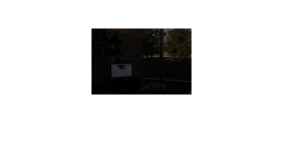

% For second arg, can also input specific demensions like [100, 100]
imshow(image)

upsized = imresize(image, 10) % Can scale up but the details will be gone

upsized = upsized(:,:,1) =

    0.0555    0.0555    0.0555    0.0555    0.0556    0.0556    0.0557    0.0558    0.0559    0.0561    0.0562    0.0563    0.0564    0.0565    0.0566    0.0567    0.0569    0.0574    0.0578    0.0583    0.0586    0.0587    0.0585    0.0580    0.0570    0.0555    0.0532    0.0503    0.0469    0.0433    0.0396    0.0359    0.0325    0.0295    0.0270    0.0253    0.0240    0.0231    0.0224    0.0221    0.0219    0.0219    0.0220    0.0221    0.0221    0.0222    0.0225    0.0230    0.0236    0.0243    0.0250    0.0257    0.0262    0.0265    0.0266    0.0263    0.0256    0.0246    0.0233    0.0220    0.0206    0.0193    0.0181    0.0172    0.0166    0.0164    0.0164    0.0165    0.0167    0.0171    0.0178    0.0186    0.0197    0.0210    0.0226    0.0244    0.0267    0.0293    0.0322    0.0353    0.0386    0.0420    0.0455    0.0489    0.0523    0.0557    0.0598    0.0646    0.0697    0.0748    0.0795    0.0836    0.0867    0.0886    0.0889    0.0873    0.0836  

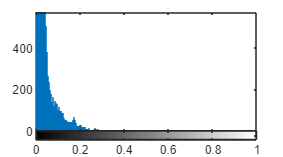


imhist(image) % Shows color distribution of image 

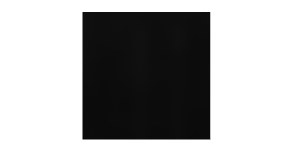


imshow(upsized(100:200, 300:400)) % Cropped image

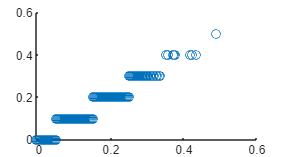


quantized = 10*image; 
quantized = uint8(quantized);   % This section quantizes the color levels from 255 to 6
quantized = double(quantized) / 10;
scatter(image(:), quantized(:)) % As we can see, there's 6 levels of color

color images 

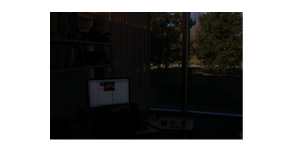

clear;
image = imread('office_1.jpg');
image = im2double(image);
image = imresize(image, 0.2);
imshow(image)   % 3 channels representing RGB

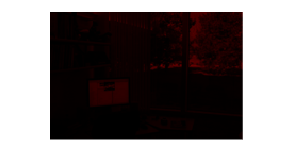


red = image;    % Show only red part of image 
red(:,:, [2,3]) = 0; % Set green and blue channels to 0 
imshow(red)

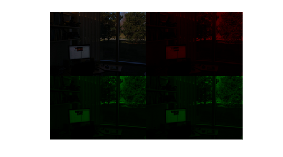


green = image; green(:,:,[1,3]) = 0;
blue = image; blue(:,:,[1,3]) = 0;

imshow([image red; green blue]); % Show all images in figure 

We can also split our image in hsv, (hue, saturation and value)

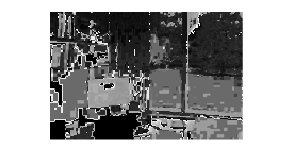

hsv_im = rgb2hsv(image);
imshow(hsv_im(:,:,1)) % Show hue

One more thing to note is the alpha channel, which is present in png formats but not jpeg formats. 

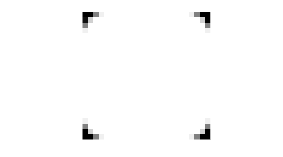

clear;
[image, ~, alpha] = imread('ArduinoExplorer_24.png');
image = im2double(image);
alpha = im2double(alpha);
imshow(alpha)

Composite images 

background = imread('baby.jpg'); 
background = im2double(background)

background = background(:,:,1) =

    0.7373    0.7373    0.7373    0.7412    0.7412    0.7451    0.7451    0.7451    0.7490    0.7529    0.7529    0.7569    0.7569    0.7529    0.7529    0.7490    0.7451    0.7451    0.7451    0.7451    0.7451    0.7451    0.7451    0.7451    0.7451    0.7451    0.7451    0.7490    0.7490    0.7529    0.7529    0.7529    0.7412    0.7373    0.7373    0.7373    0.7373    0.7412    0.7451    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7451    0.7451    0.7412    0.7412    0.7451    0.7451    0.7490    0.7451    0.7451    0.7451    0.7451    0.7451    0.7451    0.7451    0.7451    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7451    0.7451    0.7451    0.7451    0.7451    0.7451    0.7451    0.7451    0.

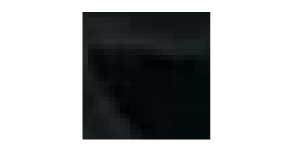

backgroundcropped = background(3500:3523, 2000:2023, :);
imshow(backgroundcropped);

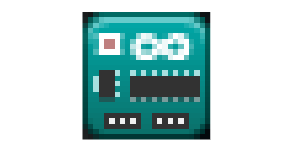


overlayed = repmat(alpha, [1 1 3]).*image + (1 - repmat(alpha, [1 1 3])).*backgroundcropped;
imshow(overlayed)